### Problem 1.2 (c)

Define variables and likelihood ratio function

a1 = 0;
b1 = 1;
a2 = 1;
b2 = 2;

x = -10:10;

lratio = (b2/b1)*exp((-(abs(x-a1)/b1)+abs(x-a2)/b2));

Plot function and format

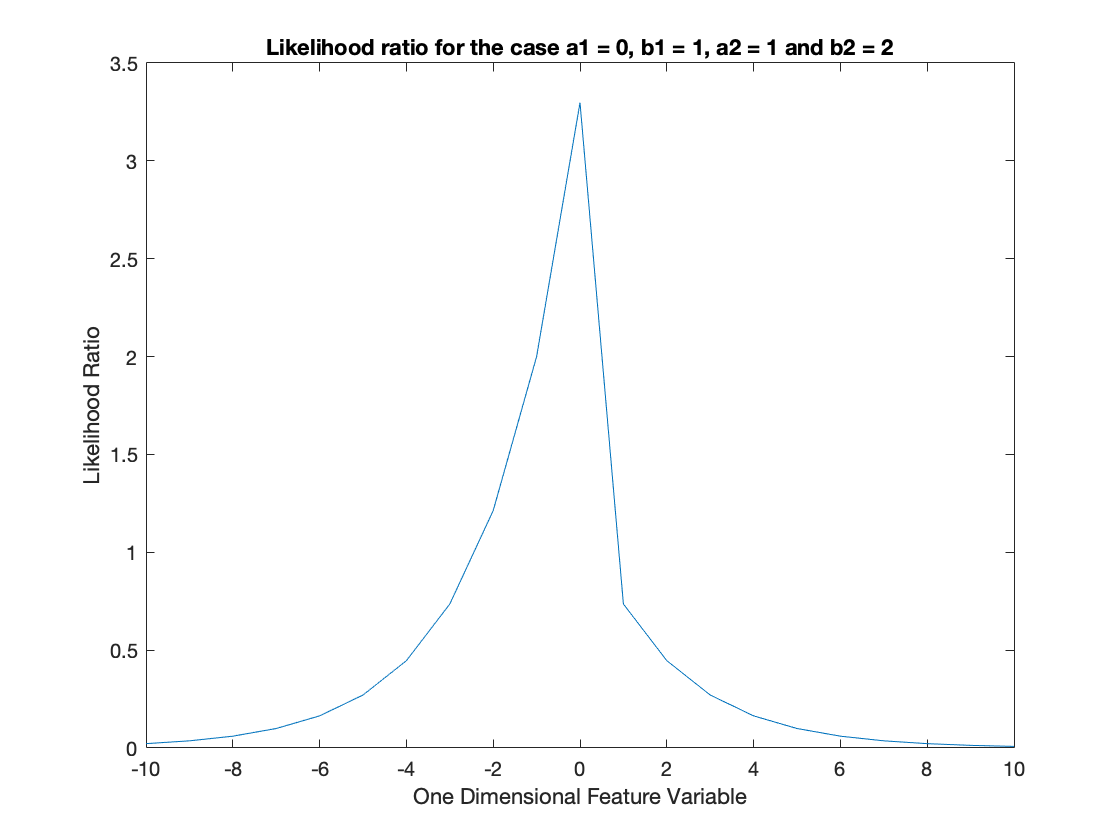

plot(x, lratio)
title('Likelihood ratio for the case a1 = 0, b1 = 1, a2 = 1 and b2 = 2')
xlabel('One Dimensional Feature Variable')
ylabel('Likelihood Ratio')

### Problem 1.4 (b)

**Part 1 (class conditional pdfs)**

Define variables

u1 = 0;
o1_2 = 1;
pw1 = 0.5;
pw2 = 0.5;

u2 = 1;
o2_2 = 2;

xrng = -10:.1:10;
norm1 = normpdf(xrng,u1,sqrt(o1_2));
norm2 = normpdf(xrng,u2,sqrt(o2_2));

Plot class conditional pdfs

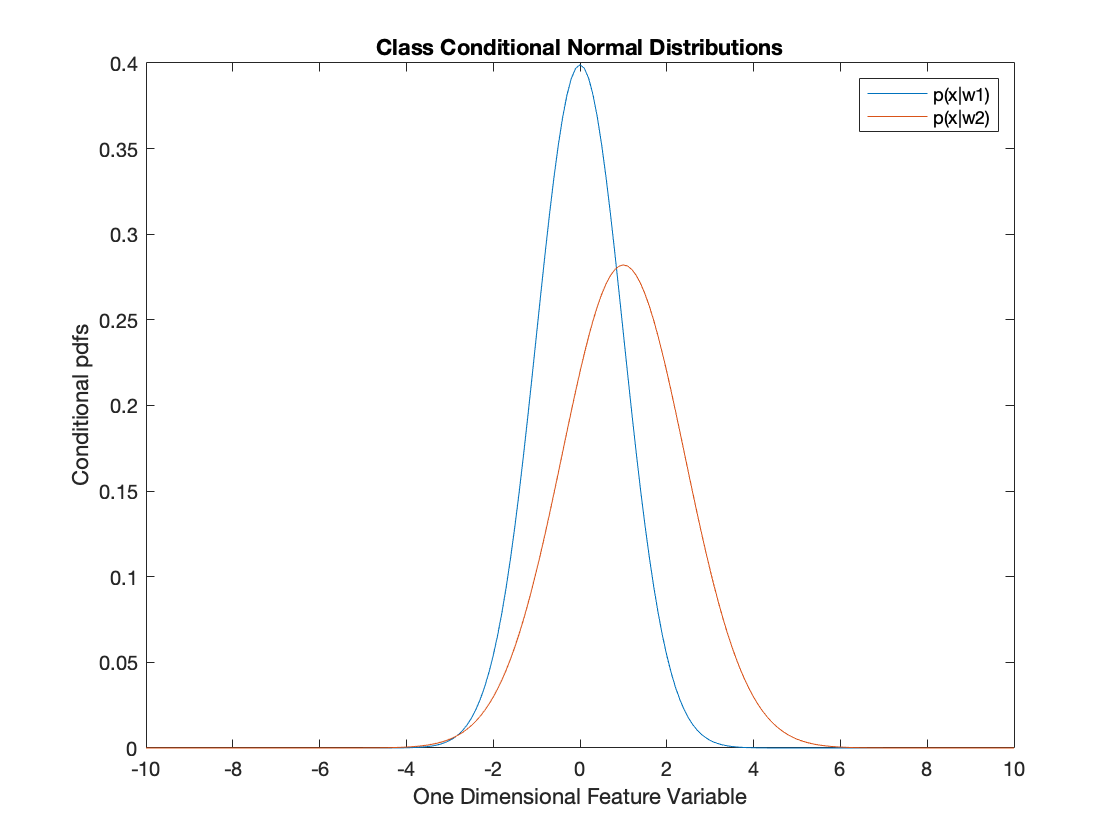

plot(xrng,norm1)
hold on
plot(xrng,norm2)
hold off

title('Class Conditional Normal Distributions')
legend('p(x|w1)', 'p(x|w2)')
xlabel('One Dimensional Feature Variable')
ylabel('Conditional pdfs')


**Part 2 (posterior probabilities)**

Define variables and plot

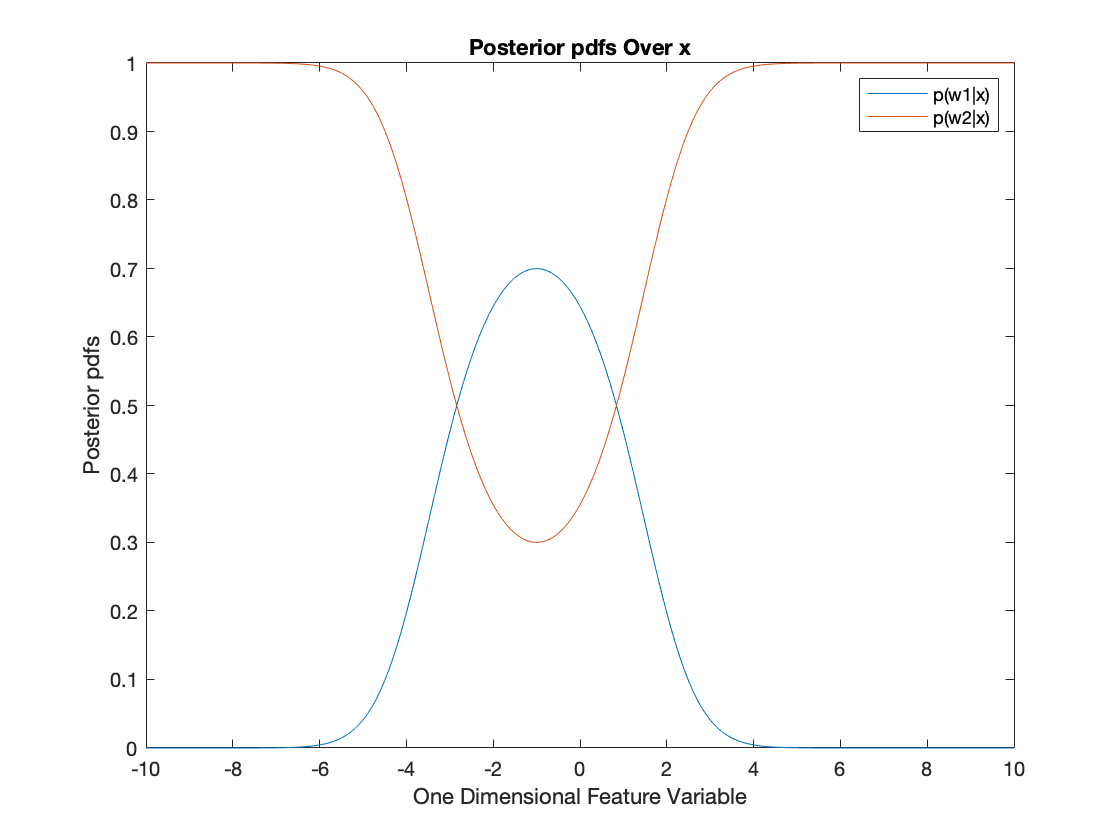

condw1 = (1./ (sqrt(2.*pi.*o1_2))).*exp(-(.5.*(xrng-u1).^2./o1_2));
condw2 = (1./ (sqrt(2.*pi.*o2_2))).*exp(-(.5.*(xrng-u2).^2./o2_2));

postw1 = condw1 * pw1 ./ ((condw1) .* pw1 + (condw2) .* pw2);
postw2 = condw2 * pw2 ./ ((condw2) .* pw2 + (condw1) .* pw1);

plot(xrng, postw1)
hold on
plot(xrng, postw2)
hold off

title('Posterior pdfs Over x')
legend('p(w1|x)', 'p(w2|x)')
xlabel('One Dimensional Feature Variable')
ylabel('Posterior pdfs')

print('Graph_1.42', '-dpng')